# Waypoint

## Definición

Dados un instante de tiempo $t$, una posición 3D $\mathbf{p}=\left\lbrack x\;y\;z\right\rbrack$, y un vector velocidad $\mathbf{v}=\left\lbrack \dot{x} \;\dot{y} \;\dot{z} \right\rbrack$, definimos un waypoint como $\mathbf{w}=\left\lbrack t\;\mathbf{p}\;\mathbf{v}\right\rbrack$.

wp = Waypoint();
wp.t = 2;
wp.setPosition([10 20 30]);
wp.setVelocity([ 2  0  0]);
wp

wp =   Waypoint with properties:

            t: 2
            x: 10
            y: 20
            z: 30
           vx: 2
           vy: 0
           vz: 0
    mandatory: 1


# Plan de vuelo TP

## Definición

Un plan de vuelo es un conjunto de waypoints en el que cada elemento tiene una información temporal diferente. Se considera que el conjunto está ordenado en el tiempo.

En un plan de vuelo TP es relevante la información de tiempo y posición incluida en los waypoints, ignorándose la información de velocidad. 

%             t  x  y  z vx vy vz
way_data = [ 05 00 05 00 00 00 00
             10 00 05 00 00 00 00
             20 00 05 05 00 00 01
             30 10 05 10 00 00 -1 
             40 10 05 00 00 00 00 
             50 10 05 00 00 00 00 ];
    
fp1  = FlightPlan(1,Waypoint.empty);
for i = 1:size(way_data,1)
    wp = Waypoint();
    wp.t = way_data(i,1);
    wp.setPosition(way_data(i,2:4));
    fp1.setWaypoint(wp);
end

fp1

fp1 =   FlightPlan with properties:

           id: 1
     priority: 0
    waypoints: [1×6 Waypoint]
         mode: TP


Asumimos que la aeronave realiza un movimiento rectilíneo y uniforme entre dos waypoints consecutivos. 

El tiempo entre ambos es

fp1.waypoints(2).timeTo(fp1.waypoints(3))

ans = 10

La dirección seguida por la aeronave es

fp1.waypoints(2).directionTo(fp1.waypoints(3))

ans =      0     0     1


y la distancia a recorrer

fp1.waypoints(2).distanceTo(fp1.waypoints(3))

ans = 5

Por último, la velocidad constante que mantiene la aeronave en dicho segmento es

fp1.waypoints(2).uniformVelocityTo(fp1.waypoints(3))

ans = 0.5000

## Visualización

Podemos mostrar el comportamiento del plan de vuelo. Para ello, es necesario indicar una resolución temporal.

time_step = 0.1;

### Posición instantánea

Podemos ver la trayectoria indicada en el plan de vuelo.

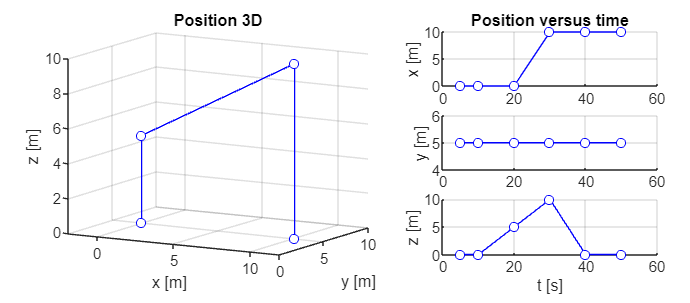

fp1.routeFigure(time_step,'b')

La gráfica izquierda muestra la ruta 3D. Los puntos se corresponden con la información de los diferentes waypoints de la secuencia.

La gráfica de la derecha muestra la evolución de la posición en el tiempo. Los puntos se corresponden con la información de los diferentes waypoints de la secuencia.

En un plan de vuelo TP, las trayectorias son continuas, pero no derivables. No está garantizado que una aeronave real pueda ejecutar la trayectoria con precisión.

### Velocidad instantánea

También podemos mostrar la velocidad instantánea del plan de vuelo.

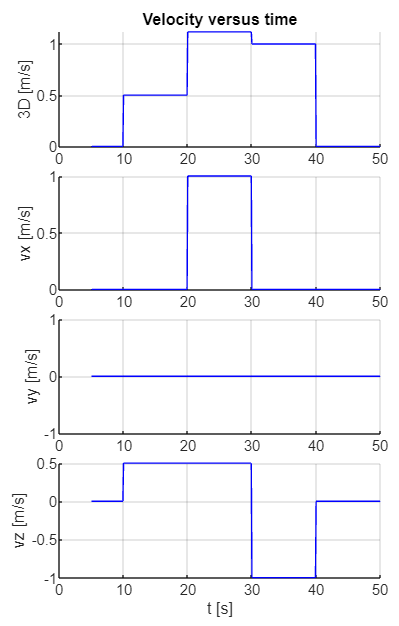

fp1.velocityFigure(time_step,'b')

La gráfica muestrá el módulo de la velocidad y su descomposición en ejes. No hay puntos con información explícita de velocidad.

Este plan de vuelo asume aceleración infinita al transitar de un segmento a otro.

# Plan de vuelo TPV

## Definición

En un plan de vuelo TPV es relevante la información de tiempo, posición **y velocidad** incluida en los waypoints. 

for i = 1:size(way_data,1)
    waypoints(i) = Waypoint();
    waypoints(i).t = way_data(i,1);
    waypoints(i).setPosition(way_data(i,2:4));
    waypoints(i).setVelocity(way_data(i,5:7));
end
fp2  = FlightPlan(2,waypoints);
fp2.mode = "TPV";

No es posible transitar desde una posición/velocidad inicial a otra posición/velocidad final aplicando un movimiento rectilíneo y uniforme. En su lugar, se realizará un movimiento curvo con aceleración variable.

## Visualización

### Posición instantánea

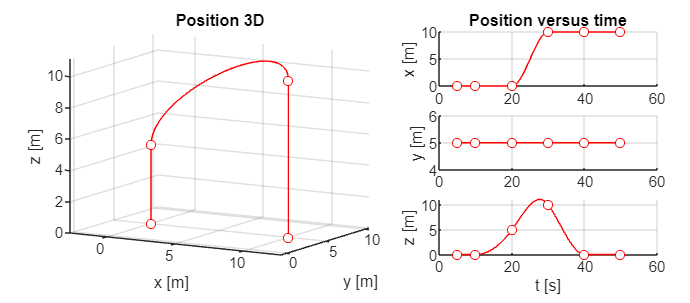

fp2.routeFigure(time_step,'r')

En esta ocasión podemos ver segmentos curvos entre waypoints consecutivos. La trayectoria completa es derivable. Una aeronave puede seguirla con precisión.

### Velocidad instantánea

También podemos mostrar la velocidad instantánea del plan de vuelo.

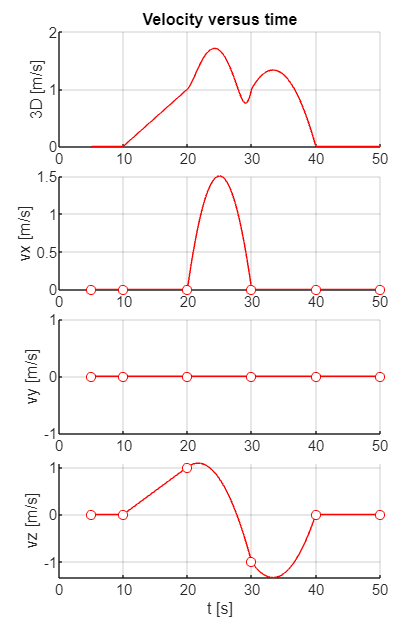

fp2.velocityFigure(time_step,'r')

En esta ocasión sí se muestra la información explícita de velocidad indicada en los waypoints.

## Distancia entre planes de vuelo

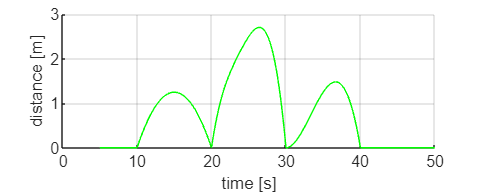

fp1.distanceFigure(fp2,time_step,'g')